# Segmenting a Moray Eel in a Reef

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

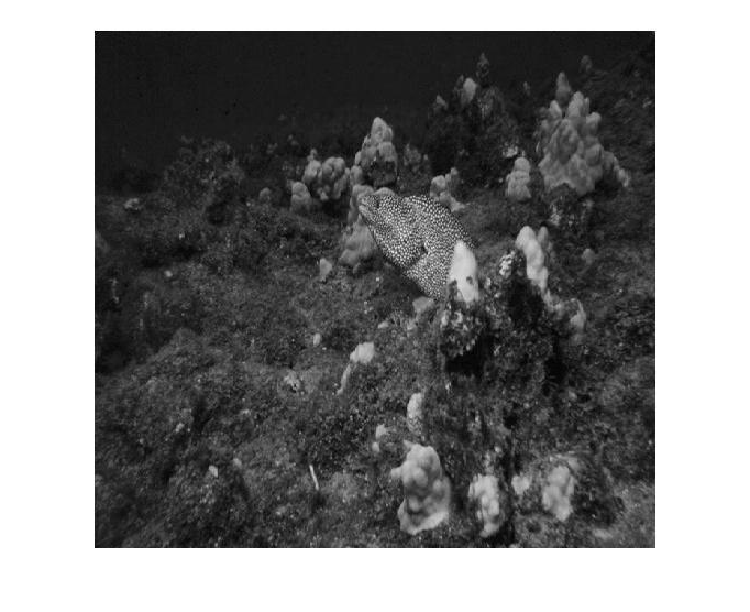

reef = imread("./images/reefGS.jpg");
imshow(reef)

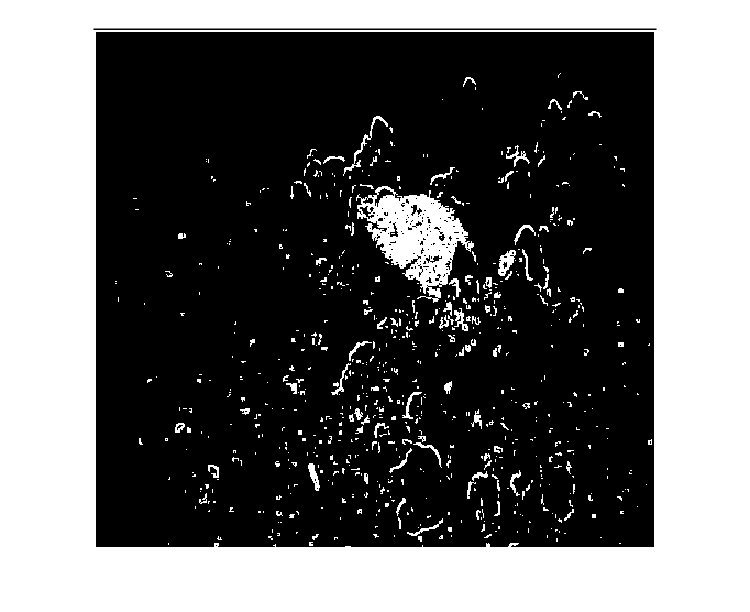


reefFilt = rangefilt(reef);
reefFilt = imadjust(reefFilt);
reefBW = imbinarize(reefFilt,.3);
imshow(reefBW)

## Task 1

This moray eel does not stand out well against the reef. Applying a range filter can get you a rough segmentation of the eel, but it needs some work to segment the entire eel and only the eel.

A lot of edges were detected because of a relatively large change in intensity between elements on the reef. These are all relatively small areas of foreground.

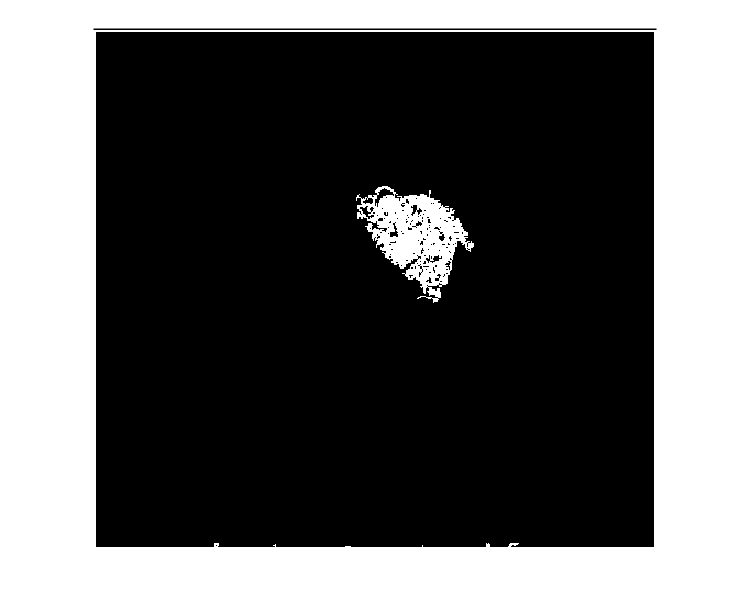

reefBW = bwareaopen(reefBW,300);
imshow(reefBW)

## Task 2

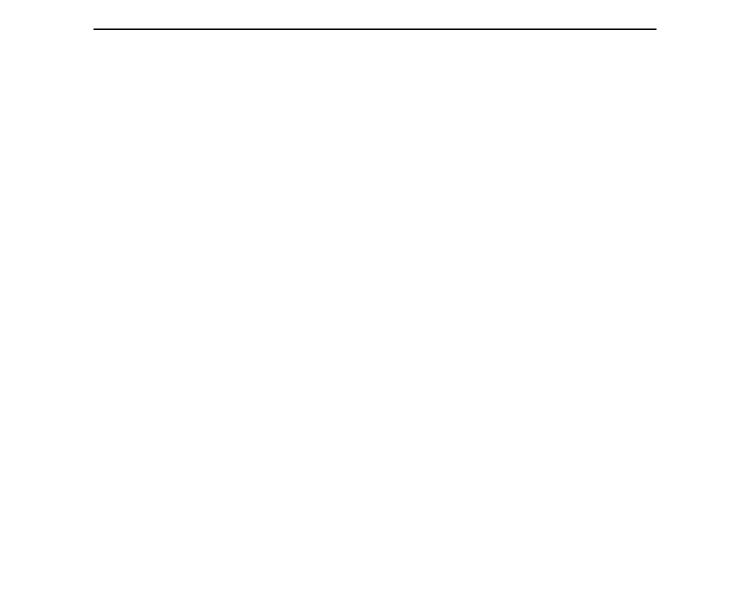

BWfilled = imfill(reefBW,"holes");
imshow(BWfilled)

## Task 3

There was a small amount of foreground along the border, which caused the entire image to be filled in.

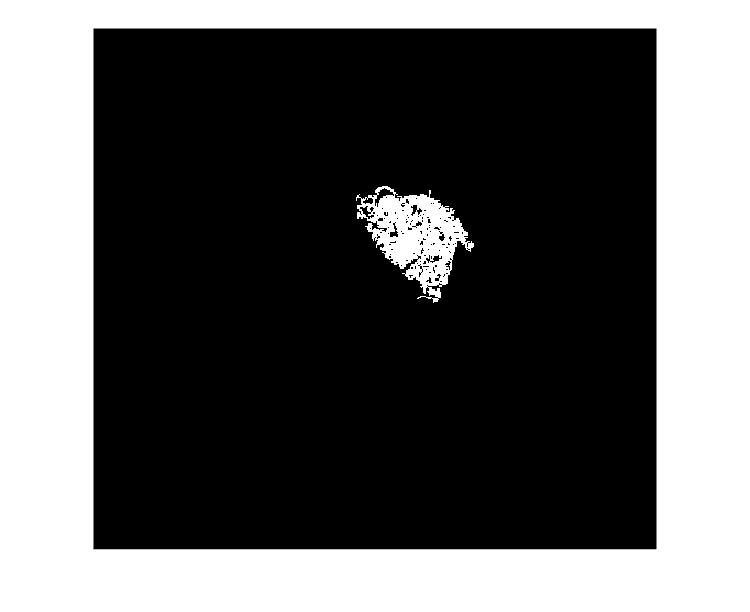

reefBW = imclearborder(reefBW);
imshow(reefBW)

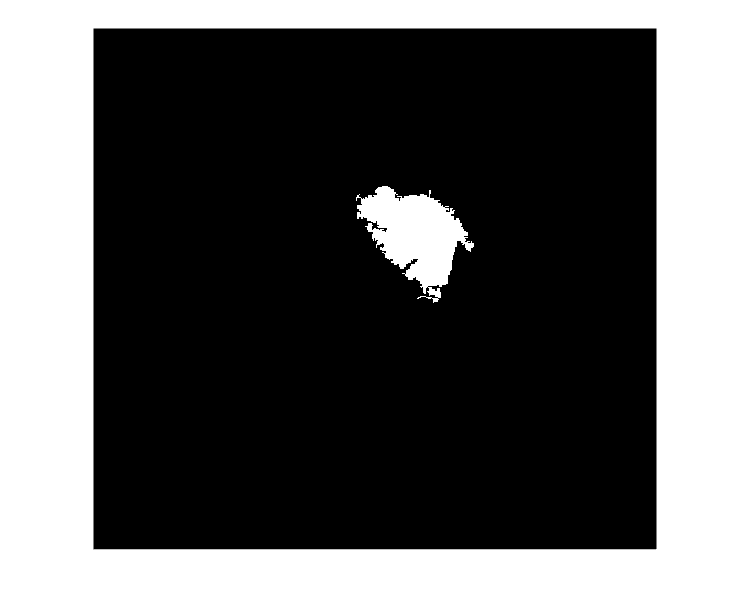

reefBW = imfill(reefBW,"holes");
imshow(reefBW)

## Task 4

SE = strel("disk",5);

## Task 5

You can perform opening operations with `imopen`.

`BW2` `=` `imopen``(``BW``,``SE``)``;`

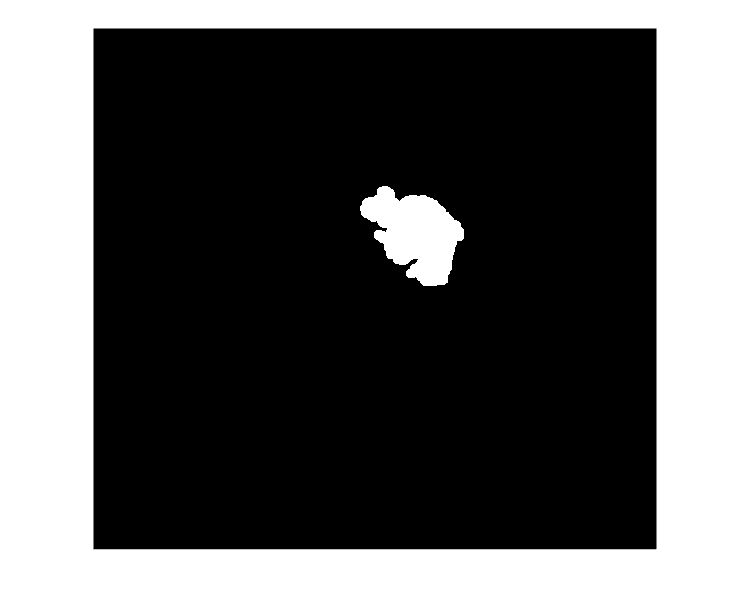

reefBW = imopen(reefBW,SE);
imshow(reefBW)

## Task 6

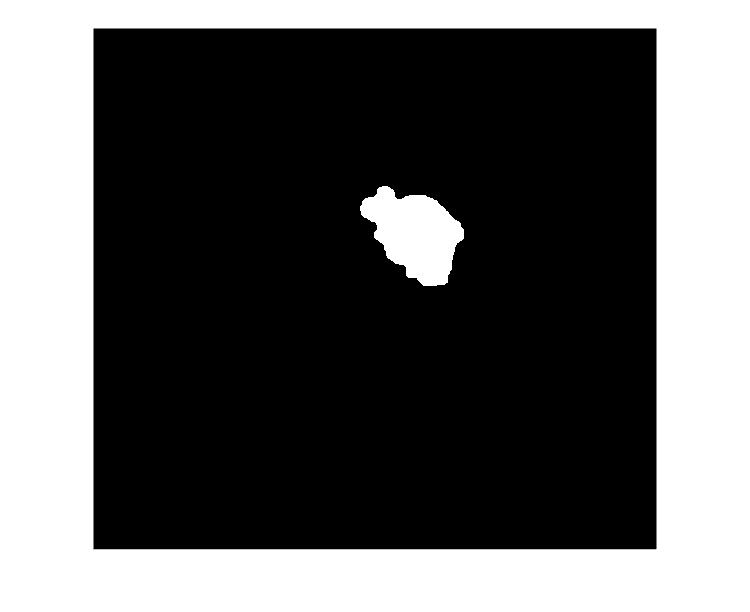

reefBW = imclose(reefBW,SE);
imshow(reefBW)